clear;clc;close all;
L = 200;
j = 10;
kT = 5;
t_max = 50;
mode = 1;
[spin, X, Y] = XYInitialization(L);
vort = XYVorticity(spin,L);
outputVideo = VideoWriter('XY_Wolff_animation_vort.avi', 'Archival');
outputVideo.FrameRate=2

outputVideo =   VideoWriter

    General Properties:

       Filename:                 'XY_Wolff_animation_vort.avi.mj2'
       Path:                     '/MATLAB Drive/PHYS 416'
       FileFormat:               'mj2'
       Duration:                 0

    Video Properties:

       ColorChannels:            []
       Height:                   []
       Width:                    []
       FrameCount:               0
       FrameRate:                2
       VideoBitsPerPixel:        []
       VideoFormat:              []
       VideoCompressionMethod:   'Motion JPEG 2000'
       CompressionRatio:         10
       LosslessCompression:      1
       MJ2BitDepth:              []

  Methods


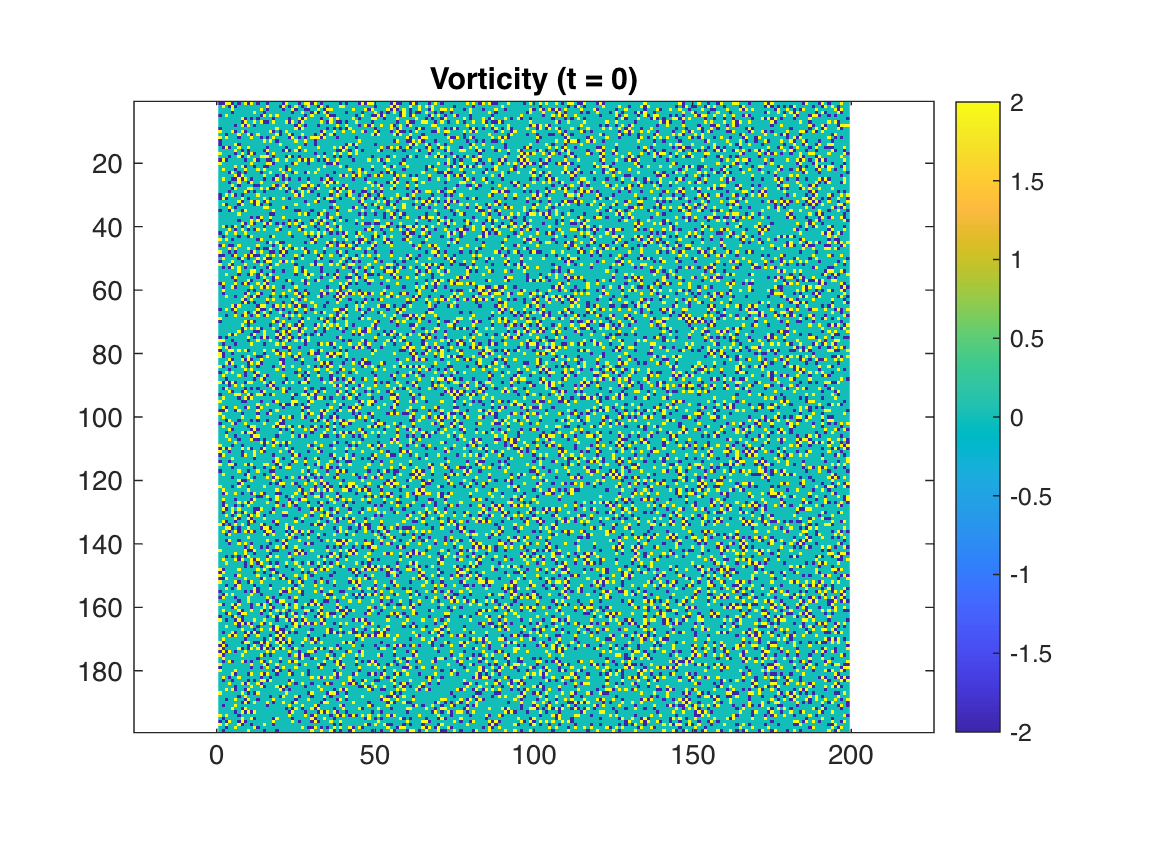

open(outputVideo);

figure(1)
imagesc(vort);
axis equal
%colormap('hsv')
colorbar
%clim([0,2])
title("Vorticity (t = 0)")
frame = getframe(gcf);

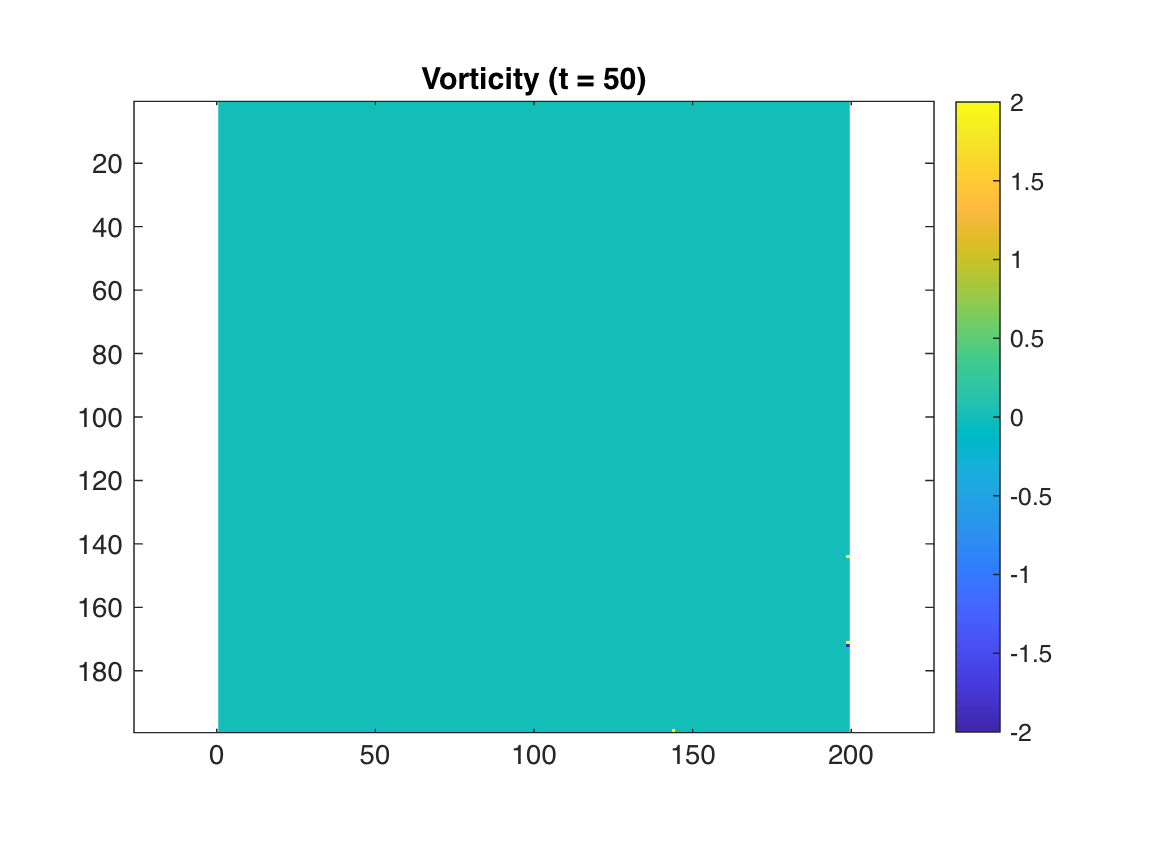


for t = 1:t_max
    [spin, X, Y, clusterMap] = XYWolff(spin, kT, j, L, mode);
    vort = XYVorticity(spin, L);
    imagesc(vort);
    axis equal
    %colormap('hsv')
    colorbar
    %clim([0,2])
    title(sprintf("Vorticity (t = %d)", t))
    frame = getframe(gcf);
    writeVideo(outputVideo, frame);
end

close(outputVideo);